## Forberedelse

Vi har en overføringsfunktion


$$G\left(s\right)=G_c \left(s\right)\cdot 4\cdot \frac{720}{s+33}\cdot \frac{1}{s}\cdot \frac{1}{24}\cdot 0\ldotp 478$$


### a)

Først har vi bare en P regulator, hvor $G_c \left(s\right)=K_P$. Vi skal finde den størst mulige værdi som opfylder kravene

- Oversving < 5%

Dette kræver 64 graders fasemargin. Dette kan vi finde ved først at tjekke hvad den mangler, og så udregne det ekstra gain vi skal bruge. Men fuck det, vi brute forcer det

clear
clc
s = tf('s');
G = 4*720/(s+33)*1/s*1/24*0.478;
KP = 9.9;
Gcl = feedback(KP*G,1);
step(Gcl)
stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.0883
    TransientTime: 0.2515
     SettlingTime: 0.2515
      SettlingMin: 0.9112
      SettlingMax: 1.0490
        Overshoot: 4.9027
       Undershoot: 0
             Peak: 1.0490
         PeakTime: 0.1814


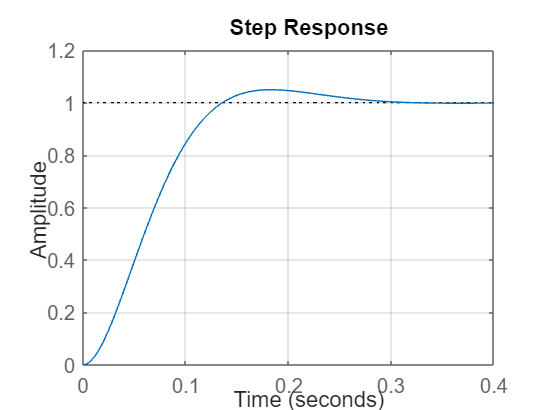

grid on

Fucking smukt. Har et oversving på 4.9%. Den stationære fejl er 0% (giver mening med det ekstra s). Settle time er omkring de 250ms.

GP = KP*G

GP =
 
     1.363e04
  --------------
  24 s^2 + 792 s
 
Continuous-time transfer function.
Model Properties


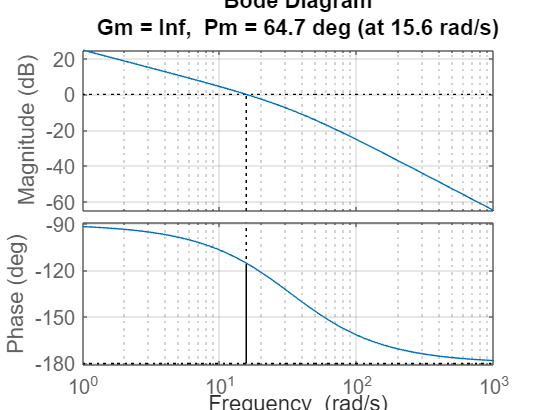

margin(GP)
grid on

Fasemarginfrekvensen er 15.6 rad/s og fasemargin 64.7 grader.

### b)

Vi slår det op tabellen, og kan se den stiger over 250ms. Så er hældningen


$$A=\frac{400}{250}=1\ldotp 6$$


Og derfra kan vi finde den stationære fejl for rampe ved at dele med DC gain, som er (har taget GP og ganget med s for type 1)


$$K_0 =\lim_{s\to 0} \frac{13630s}{24s^2 +792s}=\frac{13630}{792}=17\ldotp 2$$


Så er den stationær fejl


$$e\left(\infty \right)=\frac{A}{K_0 }=\frac{1\ldotp 6}{17\ldotp 2}=0\ldotp 09$$


Så den stationære fejl er 9%

### c)

Her smidder vi en I ind sammen med vores P og ser hvad forskellen er. Først tjekker vi step (Her TI 0.1, så 1/TI indsættes)

GI = (s+10)/s;
Gcl = feedback(G*KP,1);
Gcl2 = feedback(G*KP*GI,1);
step(Gcl2,Gcl)
stepinfo(Gcl2)

ans = struct with fields:
         RiseTime: 0.0598
    TransientTime: 0.6164
     SettlingTime: 0.6164
      SettlingMin: 0.8864
      SettlingMax: 1.4934
        Overshoot: 49.3364
       Undershoot: 0
             Peak: 1.4934
         PeakTime: 0.1661


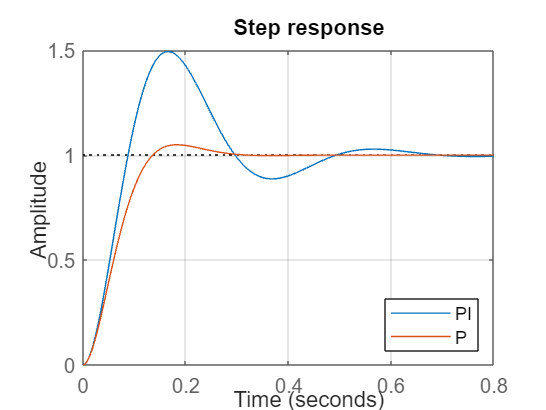

grid on
title('Step response')
legend('PI','P','Location','southeast')

Og så rampe

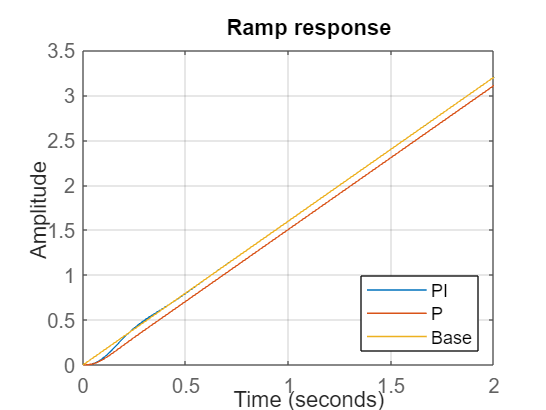

step(Gcl2*1.6/s,Gcl*1.6/s,1.6/s)
xlim([0,2])
grid on
title('Ramp response')
legend('PI','P','Base','Location','southeast')

På rampen kan vi også se at P reguleringen faktisk har de 9% stationære fejl.

Så vi har fjernet den stationære fejl på bekostning af et meget højt oversving. Dette kommer fra at vores TI er meget tæt på vores krydsfrekvens, så vi rykker meget med fasemarginen. Så fordi vores TI var så høj, så er fasen ved vores krydsfrekvens blevet presset ned.

### d)

Vi skal bruge en ny GP og så finde fasemargin og krydsfrekvens til den

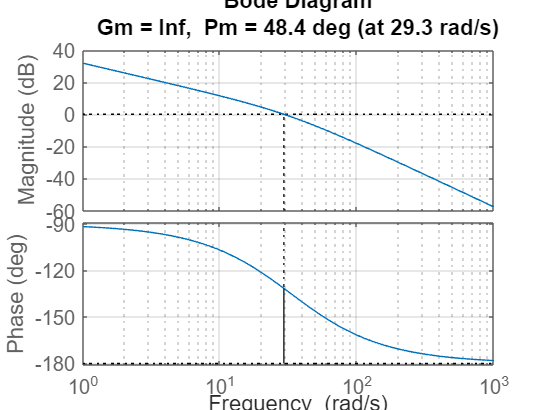

KP2 = 22.5;
GP2 = KP2*G;
margin(GP2)
grid on

Her har vi en fasemargin på 48.4 grader ved 29.3 rad/s. Vi tjekker resten med steprespons

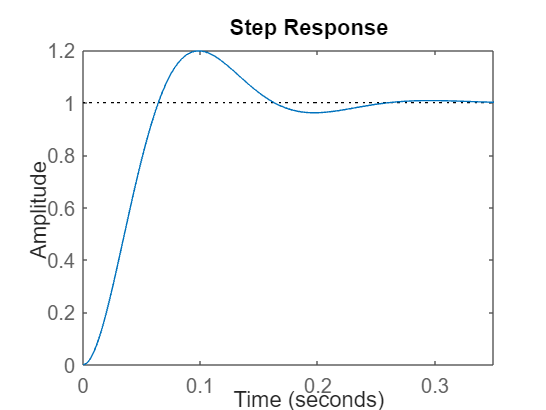

Gcl3 = feedback(G*KP2,1);
step(Gcl3)

stepinfo(Gcl3)

ans = struct with fields:
         RiseTime: 0.0435
    TransientTime: 0.2315
     SettlingTime: 0.2315
      SettlingMin: 0.9244
      SettlingMax: 1.1970
        Overshoot: 19.6961
       Undershoot: 0
             Peak: 1.1970
         PeakTime: 0.0977


Vi har intet oversving og den settler på en 230ms

### e)

Så vi skal lave en D der hæver fasen ved de 29.3 rad/s så vi har en margin på de ca. 65 grader. Deraf mangler vi at hæve med 16.5 grader.


$$G_{\textrm{PD}} \left(s\right)=K_P \left(1+\frac{{\textrm{sT}}_d }{{\textrm{sT}}_f +1}\right)$$


1/Td og 1/Tf er der vores peak er løftet/sænket med 45 grader i fasen

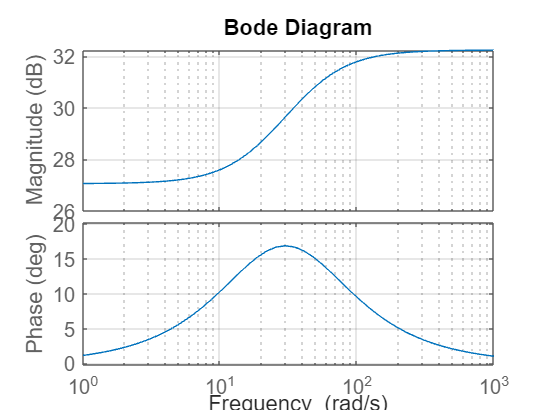

Td = 1/49.5;
Tf = 1/40.5;
GPD = KP2*(1+(s*Td)/(s*Tf+1));
bode(GPD)
grid on

Det er tæt på men det er værdierne vi kører med

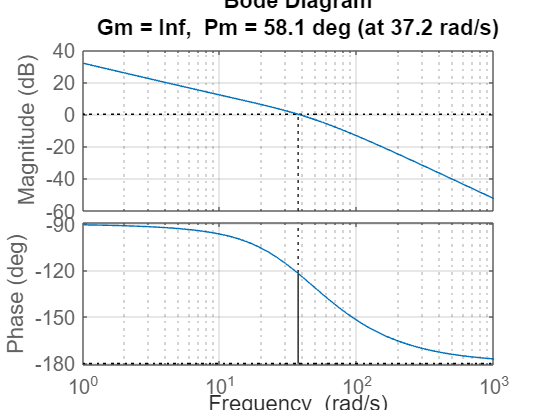

margin(GPD*G)
grid on

Så har vi problemet at vi har flyttet krydsfrekvensen, så vi skal ændre KP en smule. Vi trækker den en 8dB ned.

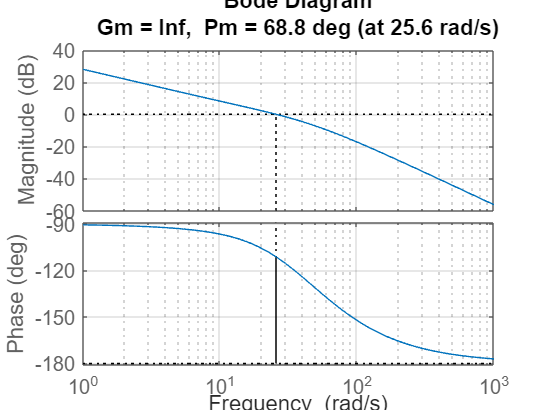

GPD2 = 14.5*(1+(s*Td)/(s*Tf+1));
margin(GPD2*G)
grid on

s

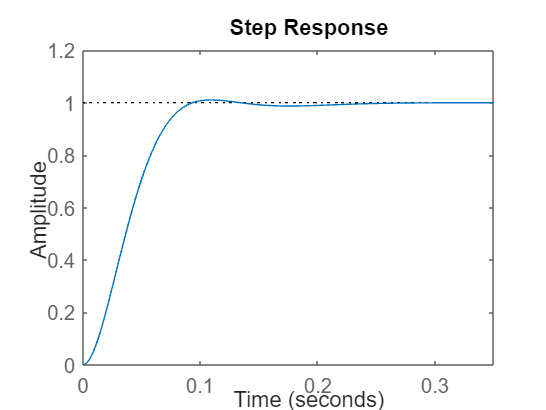

Gcl4 = feedback(G*GPD2,1);
step(Gcl4)

stepinfo(Gcl4)

ans = struct with fields:
         RiseTime: 0.0558
    TransientTime: 0.0848
     SettlingTime: 0.0848
      SettlingMin: 0.9114
      SettlingMax: 1.0102
        Overshoot: 1.0227
       Undershoot: 0
             Peak: 1.0102
         PeakTime: 0.1080


## Øvelse

1.

Ved stor nok forstyrrelse søger den ind mod dens reference (0V). Grundet modstand fra friktion ol. så kommer den ikke helt derind. Ved højere gain gør den det hurtigere, og trækker længere ind, da den ganger den lave spænding til en værdi høj nok til at drive den.

2. png0

De 5% oversving ligger højere end forventet ved et sted mellem 11.5 og 12.5. Der er en lille stationær fejl, selvom der ikke burde være. De 0 volt ændrer motorens opførsel.

3. png1

Forskellen er ca. 23.75mV hvilket er ca. 5-6% hvilket er lavere end de forventede 9%.

4. png2

Vores TI var 0.1, KP 9.9. Her har vi ingen stationær fejl på rampe og et oversving på ca. 13.75%

5. png3 png4

Oversving på ca. 47-48% på step ved forrige indstillinger. Lavere TI værdier giver et større oversving. Frekvensen vi har 0.5Hz, er lavere en 1/TI hvilket er den over frekvens vi ikke har et gain fra I regulatoren. Da vi er under den frekvens, og når vi skruer ned for TI er længere under, så stiger gain gradvist. Derfor vil vi flytte vores krydsfrekvens, og dermed falder vores fasemargin.

6. png5

KP 22.5, oversvinget er ca. 18%

7. png6 png7 png8

KP 14.5, Td 20mS, Tf 25mS. Den ligner ikke helt forventet, og har intet oversving, eller stationær fejl.

Det ser ud til at lige over de 20 går i mætning, og det er derfor vi får lidt underlige resultater. Grunden til at der intet oversving er, er nok som følge af mætning.

At sænke den lidt giver et pænere resultat.Td 15 og Tf 20 er meget pænt.

s